# Manivela

clear

EjeManivela=readtable("MatLab cinetica\Reacciones manivela\Eje-manivela-Der.txt","Delimiter"," ")

EjeManivela = 160×9 table
    Time_s_    Force_Revolution_2__ArfadaCaso1_iaa_N_    Force_X__Revolution_2__ArfadaCaso1_iaa_N_    Force_Y__Revolution_2__ArfadaCaso1_iaa_N_    Force_Z__Revolution_2__ArfadaCaso1_iaa_N_    Moment_Revolution_2__ArfadaCaso1_iaa_N_mm_    Moment_X__Revolution_2__ArfadaCaso1_iaa_N_mm_    Moment_Y__Revolution_2__ArfadaCaso1_iaa_N_mm_    Moment_Z__Revolution_2__ArfadaCaso1_iaa_N_mm_
    _______    ______________________________________    _________________________________________    _________________________________________    _________________________________________    __________________________________________    _____________________________________________    _________________________


BielaManivela=readtable("MatLab cinetica\Reacciones manivela\Biela-manivela-Der.txt","Delimiter"," ")

BielaManivela = 160×9 table
    Time_s_    Force_Z__Spherical_9__ArfadaCaso1_iaa_N_    Force_Y__Spherical_9__ArfadaCaso1_iaa_N_    Force_X__Spherical_9__ArfadaCaso1_iaa_N_    Force_Spherical_9__ArfadaCaso1_iaa_N_    Moment_Z__Spherical_9__ArfadaCaso1_iaa_N_mm_    Moment_Y__Spherical_9__ArfadaCaso1_iaa_N_mm_    Moment_X__Spherical_9__ArfadaCaso1_iaa_N_mm_    Moment_Spherical_9__ArfadaCaso1_iaa_N_mm_
    _______    ________________________________________    ________________________________________    ________________________________________    _____________________________________    ____________________________________________    ____________________________________________    __________________________________

D_manivela=0.05

D_manivela = 0.0500

d_eje=0.035

d_eje = 0.0350

b_manivela=0.02

b_manivela = 0.0200

h_manivela=D_manivela

h_manivela = 0.0500

W=0.01;
H=0.008;
L=b_manivela;

%4140 T=205
Sut=1470  

Sut = 1250

Sy=1360

Sy = 1140

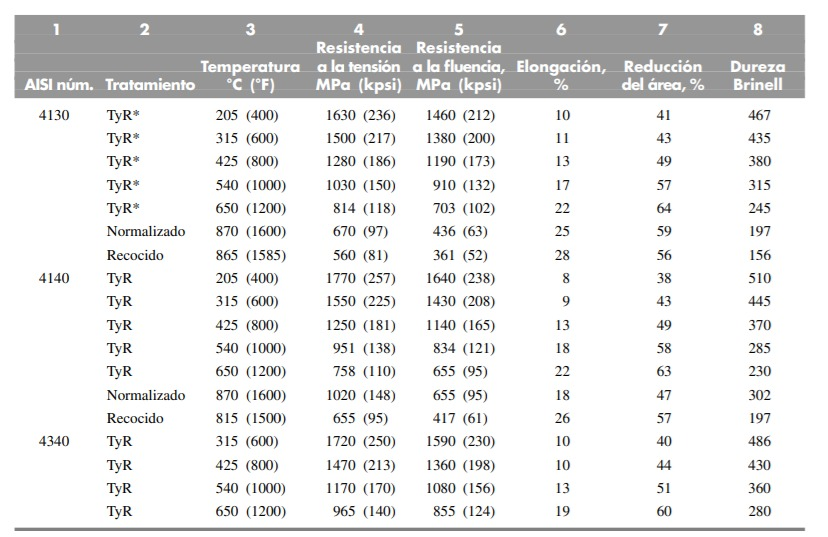

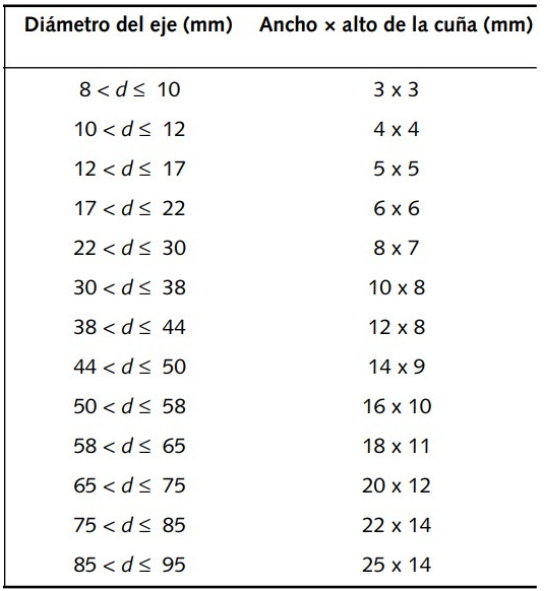



vectorToempo=BielaManivela.Time_s_;
ExtremoEjeFy=-EjeManivela.Force_X__Revolution_2__ArfadaCaso1_iaa_N_;
ExtremoEjeFz=EjeManivela.Force_Z__Revolution_2__ArfadaCaso1_iaa_N_;
ExtremoEjeFx=EjeManivela.Force_Y__Revolution_2__ArfadaCaso1_iaa_N_;
EjeTorqueMz=EjeManivela.Moment_Z__Revolution_2__ArfadaCaso1_iaa_N_mm_/1000;
EjeTorqueMx=EjeManivela.Moment_Y__Revolution_2__ArfadaCaso1_iaa_N_mm_/1000;
EjeTorqueMy=-EjeManivela.Moment_X__Revolution_2__ArfadaCaso1_iaa_N_mm_/1000;
ExtremoBielaFy=BielaManivela.Force_Z__Spherical_9__ArfadaCaso1_iaa_N_;
ExtremoBielaFz=-BielaManivela.Force_Y__Spherical_9__ArfadaCaso1_iaa_N_;
ExtremoBielaFx=BielaManivela.Force_X__Spherical_9__ArfadaCaso1_iaa_N_;



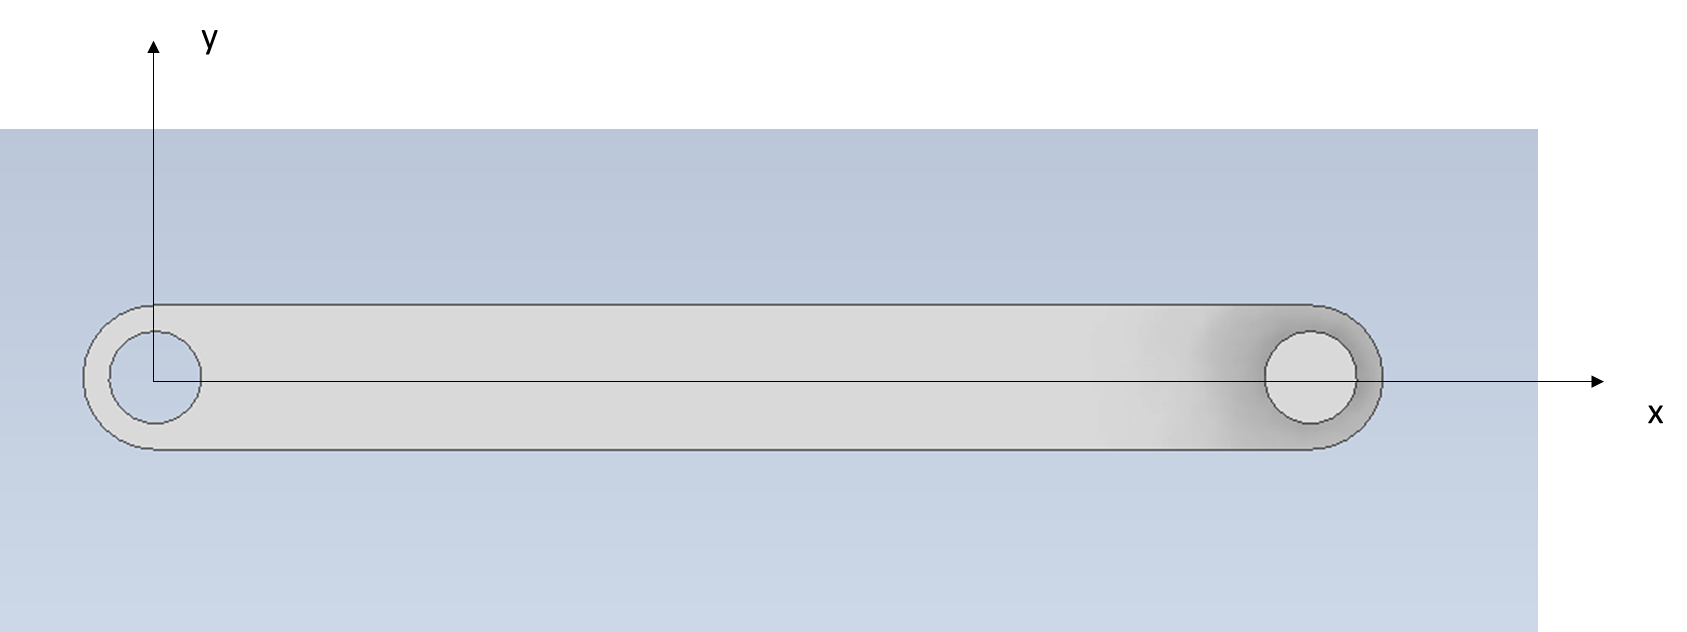

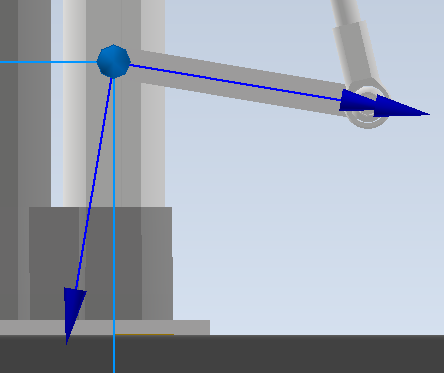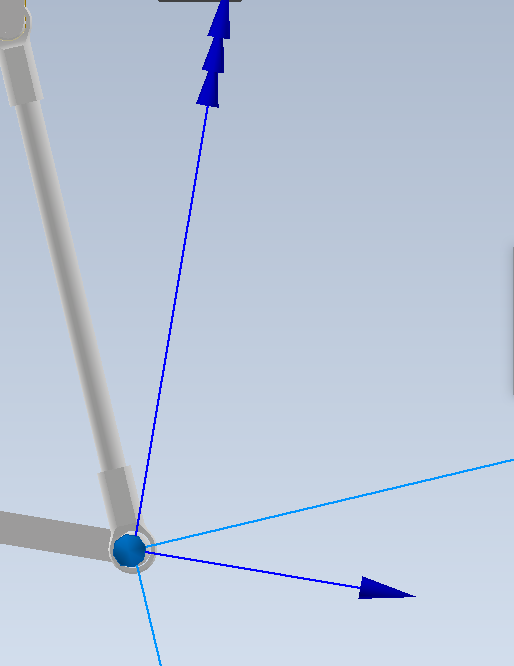

difFx=ExtremoBielaFx+ExtremoEjeFx;
difFy=ExtremoBielaFy+ExtremoEjeFy;
difFz=ExtremoEjeFz+ExtremoBielaFz;


## Análisis unión biela-manivela

ExtremoBielaFy

ExtremoBielaFz

ExtremoBielaFx

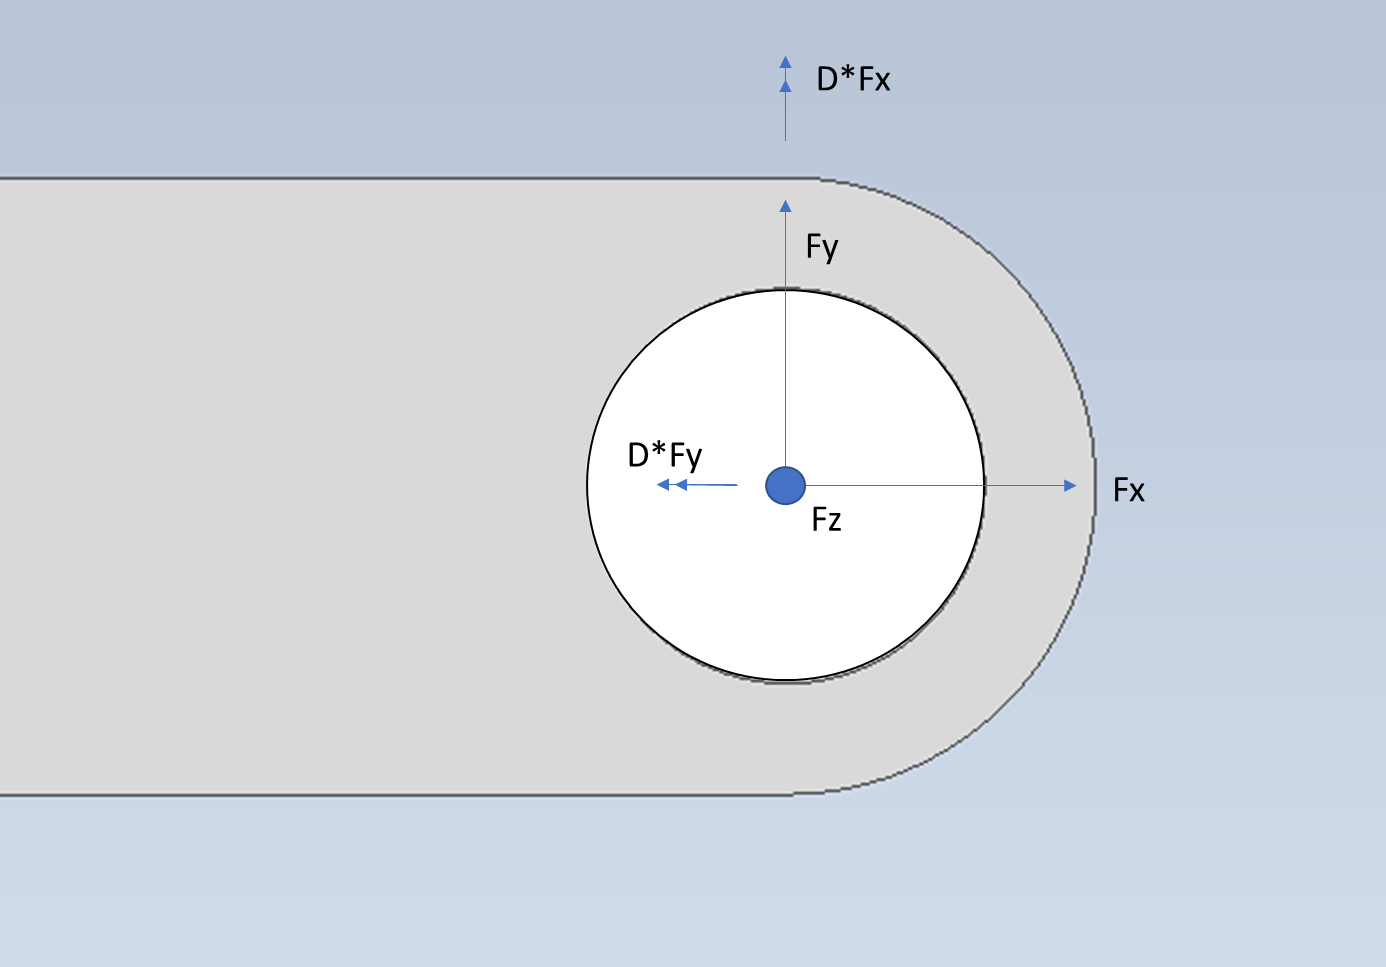

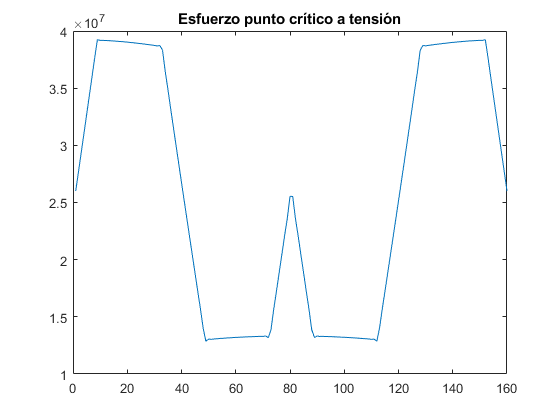

h_bm=0.0125;
D_bm=0.016;
I=pi*D_bm^4/64;
A=pi*D_bm^2/4;
My=h_bm*ExtremoBielaFx;
Mx=h_bm*ExtremoBielaFy;
MT=sqrt(My.^2+Mx.^2);

Sigma_t=MT*0.5*D_bm/I;
Sigma_c=-MT*0.5*D_bm/I;
Sigma_normal=ExtremoBielaFz/A;

Sigma_t_Total=(Sigma_normal+Sigma_t);
Sigma_c_Total=(Sigma_normal+Sigma_c);

plot(Sigma_t_Total)
title("Esfuerzo punto crítico a tensión")

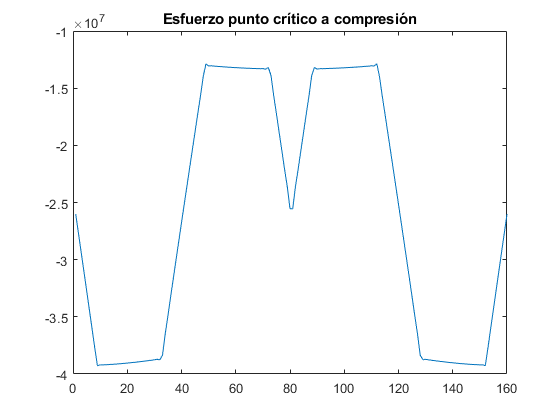


plot(Sigma_c_Total)
title("Esfuerzo punto crítico a compresión")

### Fatiga

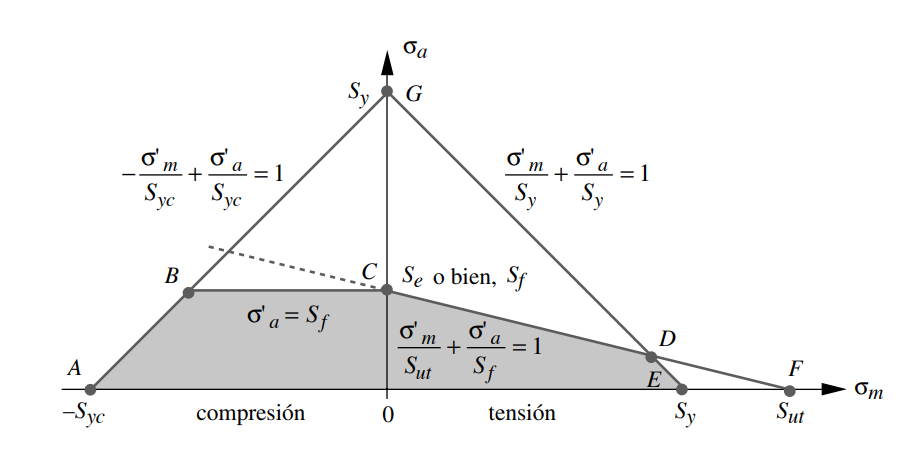

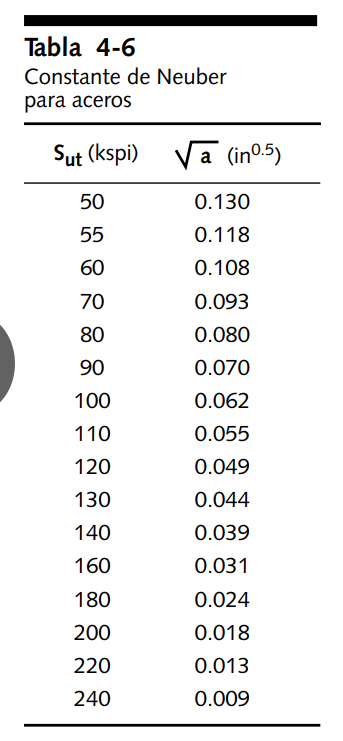

kt=2

kt = 2

neuberF=0.009 %Corregir neuber

neuberF = 0.0090

neuberT=0.005

neuberT = 0.0050

radioMuesca=0.1 %inches

radioMuesca = 0.1000

qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));

KfSold=1+qFlexion*(kt-1)

KfSold = 1.9723

KfsmSold=1+qTorsion*(kt-1)

KfsmSold = 1.9844


KtSoldadura=2

KtSoldadura = 2



mega=1000000;
sigmaA=KfSold*0.5.*abs(max(Sigma_c_Total)-min(Sigma_c_Total))/mega   %esfuerzo alternante

sigmaA = 26.0357

sigmaM=KfSold*0.5.*abs(max(Sigma_c_Total)+min(Sigma_c_Total))/mega   %esfuerzo medio

sigmaM = 51.4169

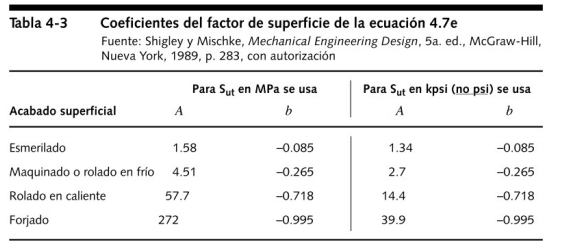

#### Factores de corrección


Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;

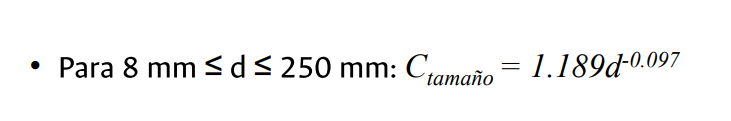

Ctam=1.189*(D_bm*1000)^(-0.097);
Ccon=0.897;
if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end




Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 347.1763

#### Diagrama de Goodman modificado

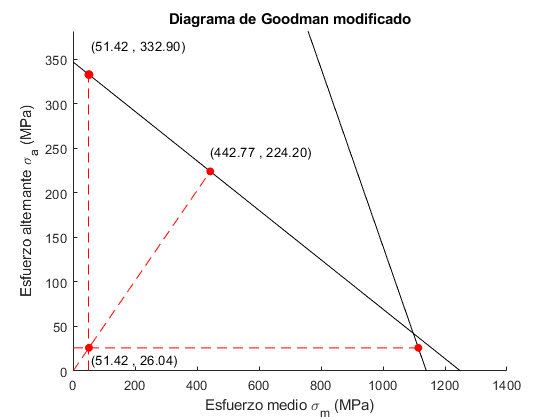

syms x1 x2
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
%text(0.6*FSy,0.9*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")

FSd11=goodManM(sigmaM)/sigmaA

FSd11 = 12.7861

FSd12=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)

FSd12 = 8.6113

FSs13=FSy/sigmaM

FSs13 = 21.6653

FSd1=min([FSd11 FSd12 FSs13])

FSd1 = 8.6113

## Análisis unión eje-manivela


A_seccion=b_manivela*(D_manivela-d_eje)

A_seccion = 3.0000e-04

J=pi/32*(D_manivela^2-d_eje^2)

J = 1.2517e-04

I=pi/64*(D_manivela^2-d_eje^2)

I = 6.2586e-05

r_externo=0.5*D_manivela

r_externo = 0.0250


Kt=1.8

Kt = 1.8000


%NPI kts

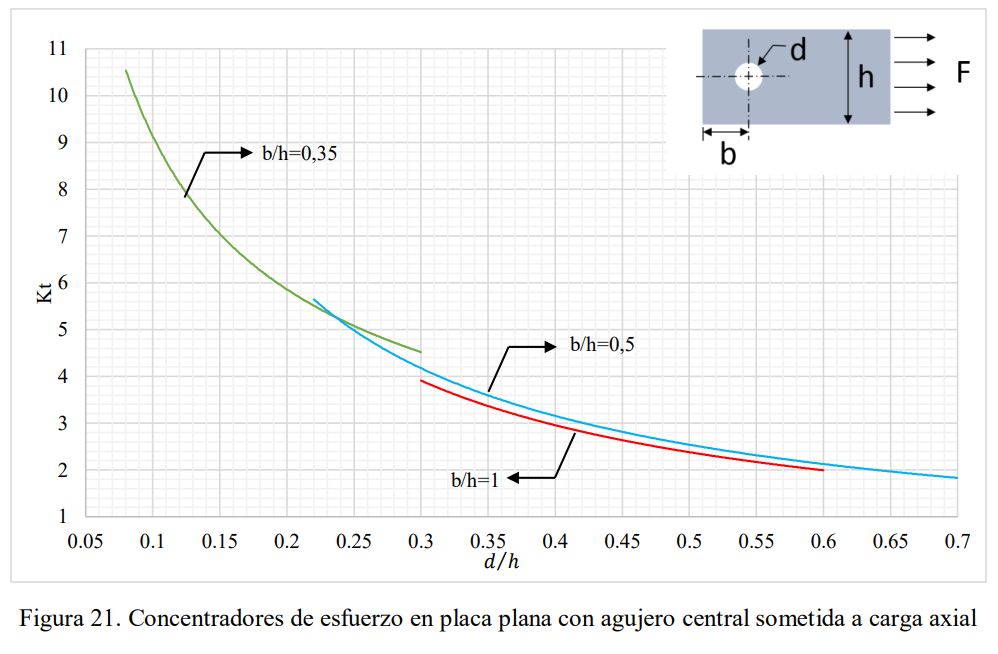

radioMuesca=0.1 %inches

radioMuesca = 0.1000

qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));
Kf=1+qFlexion*(kt-1)

Kf = 1.9723

Kfsm=1+qTorsion*(kt-1)

Kfsm = 1.9844





Sigma_Fx=ExtremoEjeFx/A_seccion;  %Carga axial:Siempre -i
Sigma_Mz=-EjeTorqueMz*r_externo/I; %Momento flector: +y->-i,-y->i
sigma_My=EjeTorqueMy*r_externo/I; %Momento flector: +z->i,-z->-i


tau_Vy=ExtremoEjeFy/A_seccion; %Carga cortante en j
tau_Vz=ExtremoEjeFz/A_seccion; %Carga cortante en k
tau_Mx=EjeTorqueMx*r_externo/J; %Momento cortante:  +y->+k,-y->-k


Sigma_total=Sigma_Fx+Sigma_Mz+sigma_My;
tau_total=sqrt(tau_Vy.^2+(tau_Vz+tau_Mx).^2);


Sigma_Alternante=0.5*(max(Sigma_total)-min(Sigma_total))

Sigma_Alternante = 9.8713e+05

Sigma_Medio=0.5*(max(Sigma_total)+min(Sigma_total))

Sigma_Medio = -7.2759e+05

Tau_Alternante=0.5*(max(tau_total)-min(tau_total))

Tau_Alternante = 1.3209e+06

Tau_Medio=0.5*(max(tau_total)+min(tau_total))

Tau_Medio = 2.6994e+06


sigmaA=sqrt((Kf*Sigma_Alternante).^2+3*(Kfsm*Tau_Alternante).^2)/mega

sigmaA = 4.9398

sigmaM=sqrt((Kf*Sigma_Medio).^2+3*(Kfsm*Tau_Medio).^2)/mega

sigmaM = 9.3884

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;

A_95=0.05*A_seccion*0.5;
d_eq=sqrt(A_95/0.0766);

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9520


Ccon=0.897;

if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 254.6199

#### Diagrama de Goodman

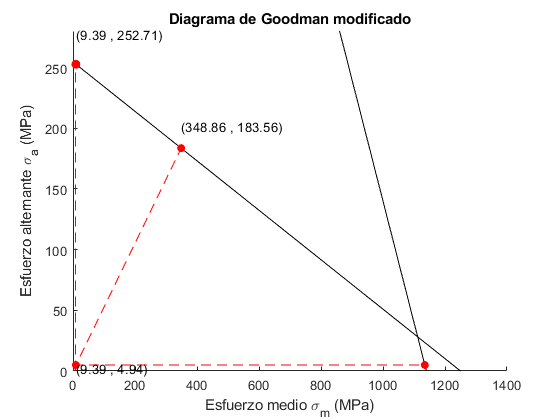

lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
%text(0.6*FSy,0.9*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")

FSd11=goodManM(sigmaM)/sigmaA

FSd11 = 51.1571

FSd12=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)

FSd12 = 37.1588

FSs13=FSy/sigmaM

FSs13 = 120.9005

FSd1=min([FSd11 FSd12 FSs13])

FSd1 = 37.1588

## Análisis cuña-cuñero Cortante

%parametros cuña


A_t=W*L;

r_eje=0.5*d_eje;
Torque=EjeTorqueMz;
r_cuna=0.03*d_eje;

k_t=1.9

k_t = 1.9000

k_ts=2.75

k_ts = 2.7500


k_f=1+qFlexion*(k_t-1)

k_f = 1.8751

k_fs=1+qTorsion*(k_ts-1)

k_fs = 2.7228


Carga_cortante=Torque/r_eje;
tau_V=k_fs*Carga_cortante/A_t;

sigmaA=sqrt(3)*0.5*(max(tau_V)-min(tau_V))/mega

sigmaA = 106.7844

sigmaM=sqrt(3)*0.5*(max(tau_V)+min(tau_V))/mega

sigmaM = 218.2050

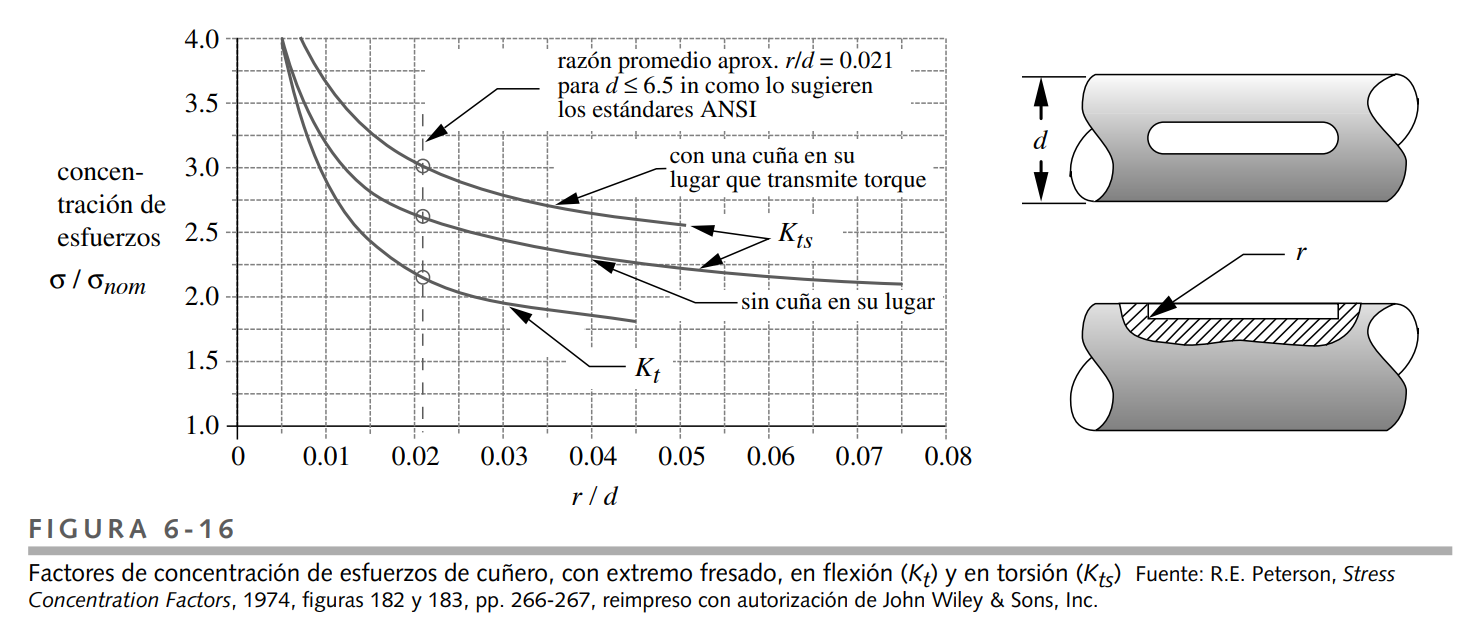

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=1; %flexion =1
Ftem=1;
Ccon=0.897;


A_95=0.05*L*W

A_95 = 1.0000e-05

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0114

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9388


if(Sut<1378.95)
    SeSC=0.5.*Sut;
else
    SeSC=689.476;
end
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 358.7028

#### Diagrama de Goodman

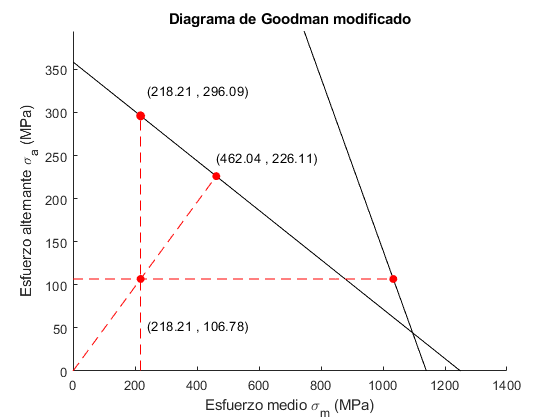

lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
%text(0.6*FSy,0.9*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")

FSd11=goodManM(sigmaM)/sigmaA

FSd11 = 2.7727

FSd12=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)

FSd12 = 2.1175

FSs13=FSy/sigmaM

FSs13 = 4.7351

FSd1=min([FSd11 FSd12 FSs13])

FSd1 = 2.1175

## Análisis cuña-cuñero aplastamiento


A_sigma=H*L;

sigma_V=k_fs*Carga_cortante/A_sigma;

sigmaA=0.5*(max(sigma_V)-min(sigma_V))/mega

sigmaA = 77.0650

sigmaM=0.5*(max(sigma_V)+min(sigma_V))/mega

sigmaM = 157.4759

#### Factores de Corrección sección cortante eje-manivela

Fsup=4.51*(Sut)^(-0.265);
Fcar=0.7; %flexion =1
Ftem=1;
Ccon=0.897;


A_95=0.05* H*W

A_95 = 4.0000e-06

d_eq=sqrt(A_95/0.0766)

d_eq = 0.0072

Ctam=1.189*(d_eq*1000)^(-0.097)

Ctam = 0.9814




SeSC=0.5*Sut;
Se=SeSC*Fsup*Fcar*Ftem*Ctam*Ccon

Se = 262.5022

#### Diagrama de Goodman

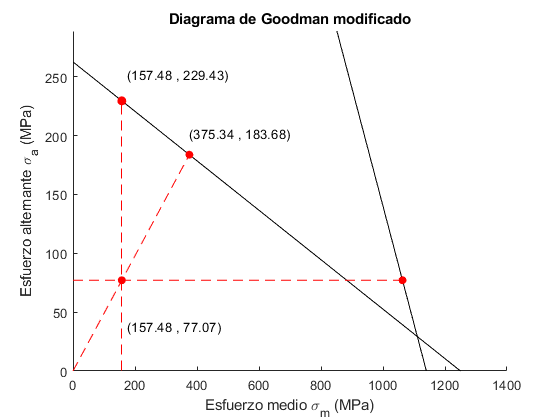

lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));

figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.1*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(FSm,1.1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
%text(0.6*FSy,0.9*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")

FSd11=goodManM(sigmaM)/sigmaA

FSd11 = 2.9771

FSd12=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)

FSd12 = 2.3835

FSs13=FSy/sigmaM

FSs13 = 6.7498

FSd1=min([FSd11 FSd12 FSs13])

FSd1 = 2.3835